clear variables
close all

load('Tests\RPC_TT_test\S11_test\SIPI_4layer.mat');
xi_train = xi_train*2-1;
xi_test = xi_test*2-1;
fpoints = linspace(1e6,1e9,334);

m = 3;
r_max = 5;
freq_order = 60;
[S11,N_coefficients,D_coefficients,n_iterations] = ...
    rpc_TT_freq(fpoints,xi_train,S11_train,xi_test,m,freq_order,'Legendre',...
    0.8,0.01,3e-3,0.9,r_max);

ans =     0.1285    0.0910


ans =     0.0753    0.0805


ans =     0.0850    0.0844


ans =     0.0863    0.0864


ans =     0.0792    0.0918


ans =     0.0782    0.1016


ans =     0.0772    0.0837


ans =     0.0767    0.0989


ans =     0.0763    0.0890


ans =     0.0761    0.1031


ans =     0.0756    0.0848


ans =     0.0750    0.1363


ans =     0.0747    0.0874


ans =     0.0742    0.0913


ans =     0.0737    0.0893


ans =     0.0731    0.0895


ans =     0.0729    0.0938


ans =     0.0730    0.1381


ans =     0.0722    0.1756


ans =     0.0724    0.0990



err1 = norm(S11-S11_test,'fro')/norm(S11_test,'fro')

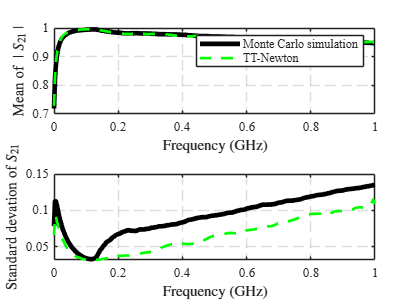

S11_mean0 = mean(abs(S11_test));
S11_sigma0 = std((S11_test));

S11_mean1 = mean(abs(S11));
S11_sigma1 = std((S11));

scale = 1e9;
freq = linspace(1000,1e9,334);
f = figure(2);
subplot(2,1,1);
hold on
plot(freq/scale,S11_mean0,'k-','LineWidth',3.5);
plot(freq/scale,S11_mean1,'g--','LineWidth',2);
legend('Monte Carlo simulation','TT-Newton')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid S_{21} \mid $','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',10)
box on;


subplot(2,1,2);
hold on
plot(freq/scale,S11_sigma0,'k-','LineWidth',3.5);
plot(freq/scale,S11_sigma1,'g--','LineWidth',2);
% ylim([0.0 0.01])
grid on
ylabel('Standard devation of $ S_{21} $','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',10)
box on;


f.Position = [100 100 675 500];


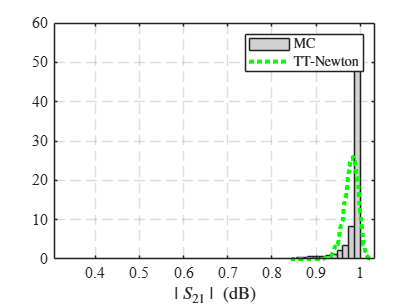

pdf_freq_idx = 100;
f = figure;
histogram(abs(S11_test(:,pdf_freq_idx)),50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N,edges] = histcounts(abs(S11(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'g:','LineWidth',3)

set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
legend('MC','TT-Newton','interpreter','LaTex');
xlabel('$ \mid S_{21} \mid $ (dB)','interpreter','LaTex')
f.Position = [100 100 675 500];